# BEV System Model - Simulation Case

modelName = "BEV_system_model";
load_system(modelName)
% Use thermal-model-enabled components.
BEV_useComponents_Thermal

Use thermal models for Motor Drive Unit and High Voltage Battery components.


VehSpdRef_loadSimulationCase_Constant( ...
  ModelName = modelName, ...
  TargetSubsystemPath = ...
    "/Controller & Environment" + ...
    "/Vehicle speed reference" )

Setting up simulation...
Simulation case: Constant
Setting simulation stop time to 1000 sec.
Selecting simulation case 5.


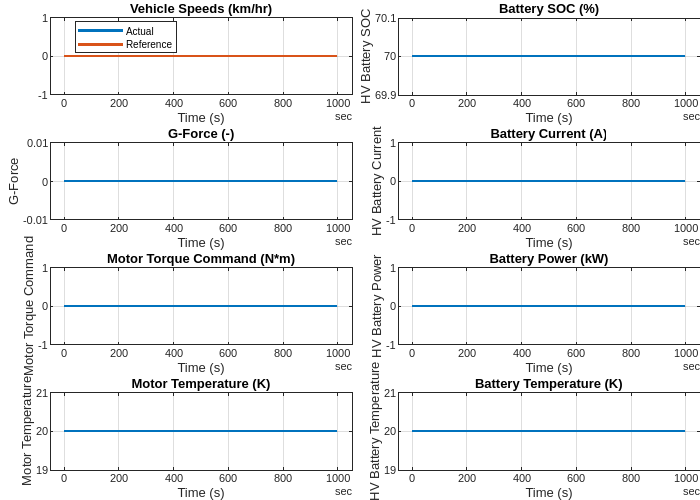

simOut = sim(modelName);
simData = extractTimetable(simOut.logsout);
fig = BEV_plotResultsCompact( SimData = simData );

*Copyright 2023 The MathWorks, Inc.*